# Symbolic Math Toolbox

Welcome to the fifth interactive tutorial of the APSC 200 MATLAB Primer. This tutorial corresponds with the Symbolic Math section of the PDF primer and provides an overview of the Symbolic Math Toolbox offered within MATLAB which will be critical in efficiently solving your design challenge.

## 1. Symbol Declaration

To declare a symbol we can make use of either the *sym* or *syms* functions.  When working with exact numerical values it is generally preferred to use the former, while the latter is more efficient at generating variables for algebraic manipulation. 

### 1.1 sym

To illustrate the nuances associated with symbolic math in MATLAB, observe the below example.

%using built-in const for pi
ans1 = sin(pi)

ans1 = 1.2246e-16

class(ans1)

ans = 'double'


%declare a symbol with an exact numeric value
Pi = sym(pi);
ans2 = sin(Pi)

$$ans2 = 0$$


%but note the class...
class(ans2)

ans = 'sym'

Using the sym function as above, complete the following examples:

Task 1:

%declare symbols for 1/4, 1/3, 5/6
a = 
b = 
c = 

%evaluate the sum of the above defined symbols algebraically 


$$ans = \frac{17}{12}$$

It is often the case where we wish to work with the numerical approximation instead of the symbolic value.  This can be accomplished using the *double* function. 

Task 2:

%evaluate the sum you found above above numerically


ans = 1.4167

More generally, *sym *can be used to define variables in a more abstract sense.  

Task 3:

%create symbols for x and y and store in variable x, and y resp.
x = 
y = 

### 1.2 syms

We can declare symbols much faster through the use of *syms* in the place of *sym*.  That being said, when we wish to declare symbols for numeric values it is still best to use *sym. *

Task 1:

%using syms declare symbols for x,y, and z


## 2. Symbolic Functions

The real usefulness of the symbolic toolbox comes in when we discuss symbolic functions.  Symbolic functions are built off of symbols and are advantageous for a number of reasons.  The goal of this section is to stress their importance. 

### 2.1 Declaration

We can declare symbolic functions in a number of different ways.  In the Section 7 of the MATLAB Primer we run through several of these methods. 

Task 1:

%using syms define the symbolic function f(x) = x^2


%verify formula using the formula keyword
formula(f)

$$ans = x^{2}$$

Task 2:

%define g(x,y) = sin(x)*cos(y)


%verify formula


$$ans = \cos\left(y\right)\,\sin\left(x\right)$$

Task 3:

%define h(x,y) = f(x) + g(x,y)


%verify formula 


$$ans = \cos\left(y\right)\,\sin\left(x\right)+x^{2}$$

### 2.2 Evaluating Symbolic Functions

Symbolic evaluation is useful from an analytical perspective, but in practice we usually work with numerical values.  The *double* function is a tool which allows us to convert a symbolic type into a double. 

Task 1:

%evaluate f(x) defined in section 2.1 at the point x=2


ans = 4

Evaluating a symbolic function over a domain is also extremely useful and allows one to easily visualize the function in question.

Task 2:

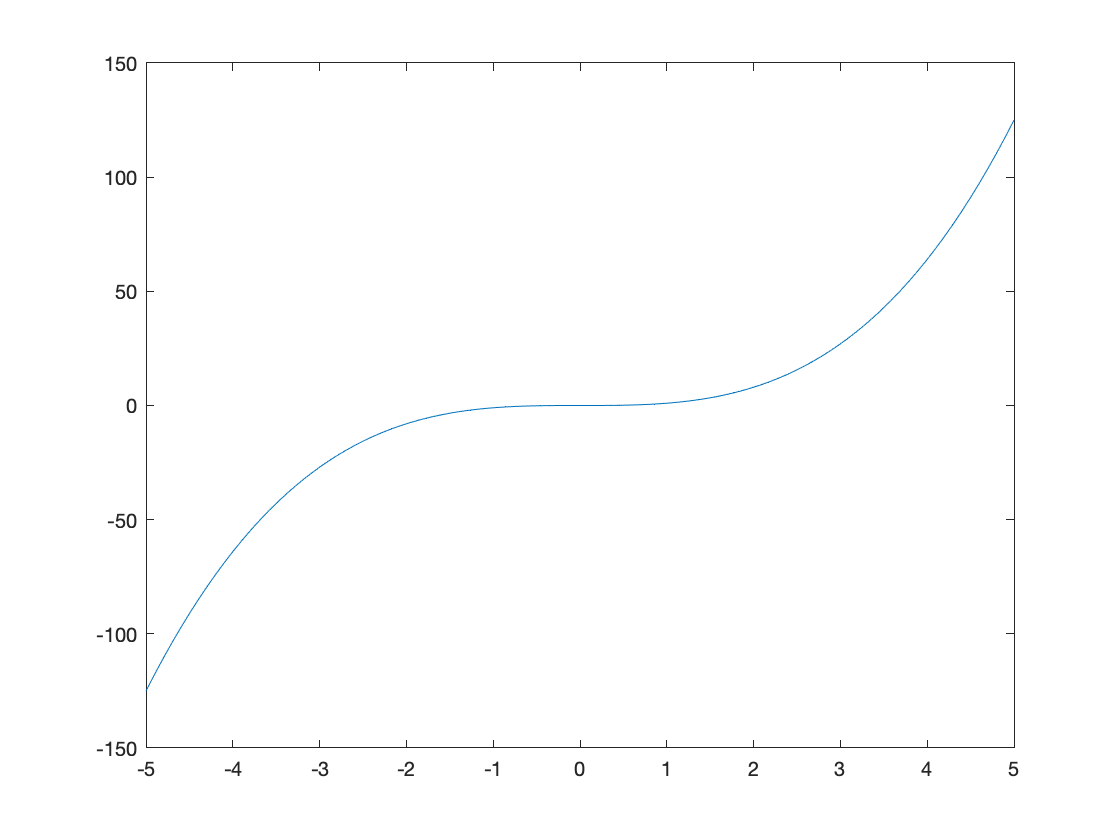

clear
%define the symbolic function f(x) = x^3


%evaluate f over the range [-5,5]


## 2.3 Function Manipulation

Referring to Section 7 in the MATLAB Primer, run the following examples.

Task 1:

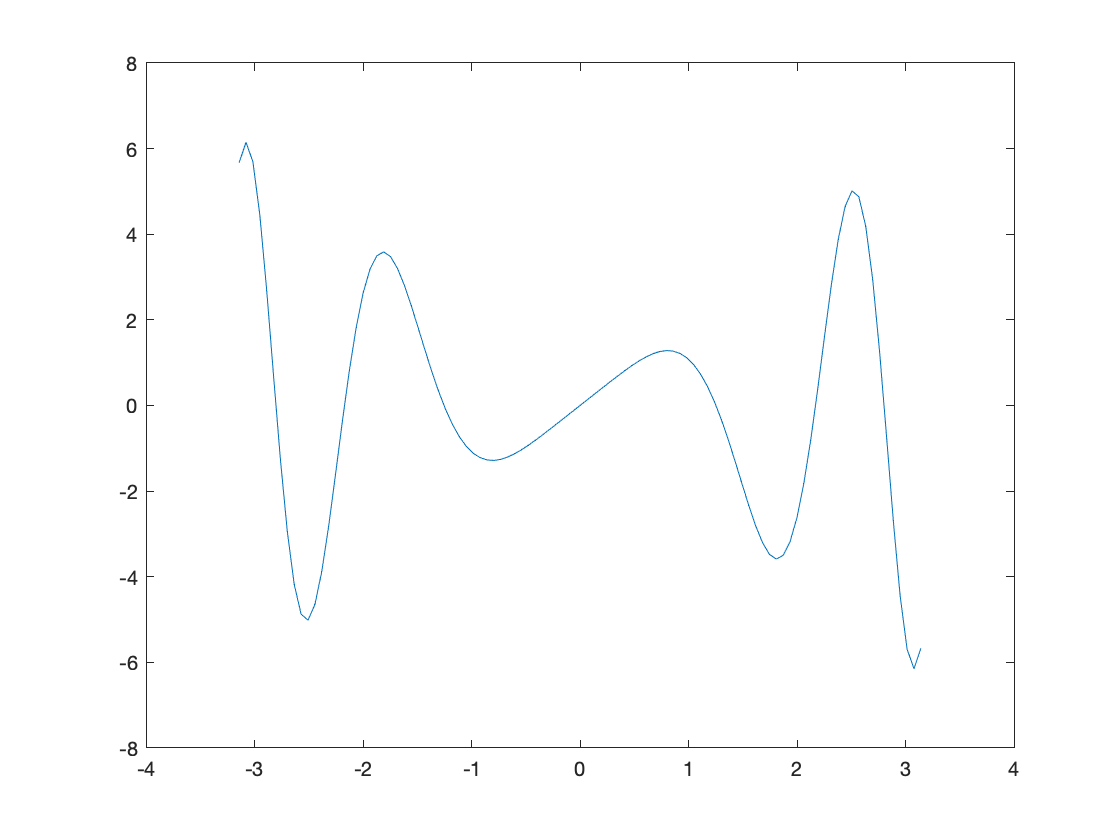

clear
syms f(x)
f(x) = sin(x^2);

%differentiate f w.r.t. x


%evaluate over [-pi,pi] and plot result


Now suppose we have a density function given by $\rho(x) = \alpha e^{-x^2}$

Task 2:

%define density symbolically


$$rho(x) = \alpha \,{\mathrm{e}}^{-x^{2}}$$


%use subs to change the value of alpha to 2


$$rho(x) = 2\,{\mathrm{e}}^{-x^{2}}$$


%integrate density over the range [-1,1] to find the mass contained


ans = 2.9873